# Nordic Seas cyclone plotting script

## Reading in all years of data to create nested directories (ERA5)

% Specify the folder where the files live
myFolder = '/mnt/storage6/robin/TempExtFolder/ERA5Nordic'

myFolder = '/mnt/storage6/robin/TempExtFolder/ERA5Nordic'

% Check to make sure the folder actually exists. Warn user if it doesn't
if ~isfolder(myFolder)
    errorMessage = sprintf('Error: The following folder does not exist:\n%s\nPlease specify a new folder.', myFolder);
    uiwait(warndlg(errorMessage));
    myFolder = uigetdir(); % Ask for a new one.
    if myFolder == 0
         % User clicked Cancel
         return;
    end
end

% Create struct containing tables for each year's data.
filePattern = fullfile(myFolder, '*.csv');
ERA5Nordic = dir(filePattern);
n = length(ERA5Nordic);

for ix = 1:n
    baseFileName = ERA5Nordic(ix).name
    fullFileName = fullfile(ERA5Nordic(ix).folder, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    % all opts as follows
    opts = delimitedTextImportOptions("NumVariables", 10);
    opts.DataLines = [2, Inf];
    opts.Delimiter = ",";
    opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "msl"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";
    [ERA5Nordic(ix).Data] = readtable(fullFileName);
    clear opts
%     idx = CGRFNordic(ix).Data.msl
end

baseFileName = '2001_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2001_ERA5_Nordic_Candidates.csv


baseFileName = '2002_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2002_ERA5_Nordic_Candidates.csv


baseFileName = '2003_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2003_ERA5_Nordic_Candidates.csv


baseFileName = '2004_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2004_ERA5_Nordic_Candidates.csv


baseFileName = '2005_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2005_ERA5_Nordic_Candidates.csv


baseFileName = '2006_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2006_ERA5_Nordic_Candidates.csv


baseFileName = '2007_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2007_ERA5_Nordic_Candidates.csv


baseFileName = '2008_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2008_ERA5_Nordic_Candidates.csv


baseFileName = '2009_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2009_ERA5_Nordic_Candidates.csv


baseFileName = '2010_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2010_ERA5_Nordic_Candidates.csv


baseFileName = '2011_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2011_ERA5_Nordic_Candidates.csv


baseFileName = '2012_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2012_ERA5_Nordic_Candidates.csv


baseFileName = '2013_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2013_ERA5_Nordic_Candidates.csv


baseFileName = '2014_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2014_ERA5_Nordic_Candidates.csv


baseFileName = '2015_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2015_ERA5_Nordic_Candidates.csv


baseFileName = '2016_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2016_ERA5_Nordic_Candidates.csv


baseFileName = '2017_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2017_ERA5_Nordic_Candidates.csv


baseFileName = '2018_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2018_ERA5_Nordic_Candidates.csv


baseFileName = '2019_ERA5_Nordic_Candidates.csv'

Now reading /mnt/storage6/robin/TempExtFolder/ERA5Nordic/2019_ERA5_Nordic_Candidates.csv



% Masking longitude values into -180 to 180
for ii = 1:19
    [rows, cols] = size(ERA5Nordic(ii).Data);
    NordicCandidatesA = table2array(ERA5Nordic(ii).Data);
    for k = 1:rows
        if NordicCandidatesA(k,8) > 180
            NordicCandidatesA(k,8) = (NordicCandidatesA(k,8)-360);
            ERA5Nordic(ii).Data = array2table(NordicCandidatesA);
            ERA5Nordic(ii).Data = renamevars(ERA5Nordic(ii).Data,["NordicCandidatesA1","NordicCandidatesA2","NordicCandidatesA3","NordicCandidatesA4","NordicCandidatesA5","NordicCandidatesA6","NordicCandidatesA7","NordicCandidatesA8","NordicCandidatesA9","NordicCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
        end
    end
end

% Fix variable names in tables
for iz = 1:19
    ERA5Nordic(iz).Data = renamevars(ERA5Nordic(iz).Data,["Var1","Var2","Var3","Var4","Var5","Var6","Var7","Var8","Var9","Var10"],["track_id","year","month","day","hour","i","j","lon","lat","msl"]);
end     % don't worry about the error that shows up for the previous line

Error using tabular/renamevars
Unrecognized table variable name 'Var1'.


% Removing all tracks that last longer than 10 days (70 timesteps)
for ix = 1:19
    y = max(ERA5Nordic(ix).Data.track_id);
    for b = 0:y
        count = countTimesteps(ERA5Nordic(ix).Data, b);
        if count > 70
            ERA5Nordic(ix).Data(ERA5Nordic(ix).Data.track_id == b,:)=[];
        end
    end
end

## Import data (individual years)


opts = delimitedTextImportOptions("NumVariables", 10);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["track_id", "year", "month", "day", "hour", "i", "j", "lon", "lat", "VarName10"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
NordicCandidates = readtable("/mnt/storage6/robin/TempExtFolder/2002_Nordic_Candidates3h.csv", opts);
clear opts

## Masking longitude values into -180 - 180

[rows, cols] = size(NordicCandidates);
NordicCandidatesA = table2array(NordicCandidates);
for k = 1:rows
    if NordicCandidatesA(k,8) > 180
        NordicCandidatesA(k,8) = (NordicCandidatesA(k,8)-360);
        NordicCandidates = array2table(NordicCandidatesA);
        NordicCandidates = renamevars(NordicCandidates,["NordicCandidatesA1","NordicCandidatesA2","NordicCandidatesA3","NordicCandidatesA4","NordicCandidatesA5","NordicCandidatesA6","NordicCandidatesA7","NordicCandidatesA8","NordicCandidatesA9","NordicCandidatesA10"],["track_id","year","month","day","hour","i","j","lon","lat","VarName10"]);
    end
end

% wrapTo180(NordicCandidates.lon)

## Plots to make

% One that shows tracks for different months in different colours (and also has intensity?)
% One that colour codes tracks in bins by intensity within months or seasons

## Monthly colour coded track plots for each year

% This is just pasted from the Lab script for now

sa = {'2002 Labrador Sea CGRF','2003 Labrador Sea CGRF','2004 Labrador Sea CGRF','2005 Labrador Sea CGRF','2006 Labrador Sea CGRF','2007 Labrador Sea CGRF','2008 Labrador Sea CGRF','2009 Labrador Sea CGRF','2010 Labrador Sea CGRF','2011 Labrador Sea CGRF','2012 Labrador Sea CGRF','2013 Labrador Sea CGRF','2014 Labrador Sea CGRF','2015 Labrador Sea CGRF','2016 Labrador Sea CGRF','2017 Labrador Sea CGRF','2018 Labrador Sea CGRF','2019 Labrador Sea CGRF'};
% cc = colororder(gem12); % gem12 is relatively colorblind-friendly I think
% dd = colororder(glow12);
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880]

for xx = 1:18
    i = max(CGRFLab(xx).Data.track_id);
    Jan = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 1, :); % Defining tables for each month's data
    Feb = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 2, :);
    Mar = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 3, :);
    Apr = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 4, :);
    May = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 5, :);
    Jun = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 6, :);
    Jul = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 7, :);
    Aug = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 8, :);
    Sep = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 9, :);
    Oct = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 10, :);
    Nov = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 11, :);
    Dec = CGRFLab(xx).Data(CGRFLab(xx).Data.month == 12, :);
    for b = 0:i
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',mycolours(1,:)); % colours specified so that DJF will be easy to visualize
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',mycolours(2,:));
        hold on 
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',mycolours(3,:));
        hold on 
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'.-','Color',mycolours(4,:));
        hold on 
        latMay = May.lat(May.track_id == b);
        lonMay = May.lon(May.track_id == b);
        geoplot(latMay,lonMay,'.-','Color',mycolours(5,:));
        hold on 
        latJun = Jun.lat(Jun.track_id == b);
        lonJun = Jun.lon(Jun.track_id == b);
        geoplot(latJun,lonJun,'.-','Color',mycolours(6,:));
        hold on 
        latJul = Jul.lat(Jul.track_id == b);
        lonJul = Jul.lon(Jul.track_id == b);
        geoplot(latJul,lonJul,'.-','Color',mycolours(7,:));
        hold on 
        latAug = Aug.lat(Aug.track_id == b);
        lonAug = Aug.lon(Aug.track_id == b);
        geoplot(latAug,lonAug,'.-','Color',mycolours(8,:));
        hold on 
        latSep = Sep.lat(Sep.track_id == b);
        lonSep = Sep.lon(Sep.track_id == b);
        geoplot(latSep,lonSep,'.-','Color',mycolours(9,:));
        hold on 
        latOct = Oct.lat(Oct.track_id == b);
        lonOct = Oct.lon(Oct.track_id == b);
        geoplot(latOct,lonOct,'.-','Color',mycolours(10,:));
        hold on 
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'.-','Color',mycolours(11,:));
        hold on 
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'.-','Color',mycolours(12,:));
        hold on 
    end
    geobasemap('topographic')
    title(sa(xx))
    exportgraphics(gca, ['Tracks' num2str(xx+2001) 'LabTEST.png'],"Resolution",300);
    clf
end

## Making the figure

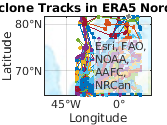

j = max(NordicCandidates.track_id);

for c = 0:j
    lat3 = NordicCandidates.lat(NordicCandidates.track_id == c);
    lon3 = NordicCandidates.lon(NordicCandidates.track_id == c);
    geoplot(lat3,lon3,'.-')
    geolimits([61 81],[-36 0])
    hold on
end
geobasemap('topographic')
title('2002 Cyclone Tracks in ERA5 Nordic Seas (3h)')

## Exporting the figure

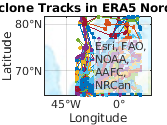

exportgraphics(gca,"NordicERA520023h.png","Resolution",300)

## Monthly plots

% month1 = NordicCandidates((month=1),:)
% for month1 = 1:12
%     for c = 0:j
%         lat3 = NordicCandidates.lat(NordicCandidates.track_id == c);
%         lon3 = NordicCandidates.lon(NordicCandidates.track_id == c);
%         geoplot(lat3,lon3,'.-')
%         geolimits([61 81],[324 360]) % FIX THIS
%         geobasemap('colorterrain')
%         title(['month',num2str(month),'tracks'])
%     end
% end

% for c = 0:j
%     switch NordicCandidates.month 
%         case 1
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 2
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 3
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 4
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 5
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 6
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 7
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 8
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 9
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 10
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 11
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%         case 12
%             geoplot(lat3,lon3,'.-')
%             geolimits([61 81],[324 360]) % FIX THIS
%             hold on
%             geobasemap('colorterrain')
%             title(['month',num2str(month),'tracks'])
%     end
% end

## Defining tables for each month's data

Jan = NordicCandidates(NordicCandidates.month == 1, :);
Feb = NordicCandidates(NordicCandidates.month == 2, :);
Mar = NordicCandidates(NordicCandidates.month == 3, :);
Apr = NordicCandidates(NordicCandidates.month == 4, :);
May = NordicCandidates(NordicCandidates.month == 5, :);
Jun = NordicCandidates(NordicCandidates.month == 6, :);
Jul = NordicCandidates(NordicCandidates.month == 7, :);
Aug = NordicCandidates(NordicCandidates.month == 8, :);
Sep = NordicCandidates(NordicCandidates.month == 9, :);
Oct = NordicCandidates(NordicCandidates.month == 10, :);
Nov = NordicCandidates(NordicCandidates.month == 11, :);
Dec = NordicCandidates(NordicCandidates.month == 12, :);

## Monthly plots

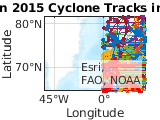

k = max(Jan.track_id);
for d = 0:k
    latj = Jan.lat(Jan.track_id == d);
    lonj = Jan.lon(Jan.track_id == d);
    geoplot(latj,lonj,'.- red')
    geolimits([61 81],[324 20])
    hold on
end
geobasemap('topographic')
title('Jan 2015 Cyclone Tracks in ERA5')

## Plotting JFM storms for each year & all years: CGRF

% Load up cells with JFM tracks for each year
load CGRFNordicwinters.mat
colHeadings = {'Years' 'Data'};
CGRFNordicW = cell2struct(CGRFNordicwinters,colHeadings,2)

CGRFNordicW = 18×1 struct array with fields:
    Years
    Data



% Plotting all JFM storms for each individual year
sa = {'2002 JFM Nordic CGRF','2003 JFM Nordic CGRF','2004 JFM Nordic CGRF','2005 JFM Nordic CGRF','2006 JFM Nordic CGRF','2007 JFM Nordic CGRF','2008 JFM Nordic CGRF','2009 JFM Nordic CGRF','2010 JFM Nordic CGRF','2011 JFM Nordic CGRF','2012 JFM Nordic CGRF','2013 JFM Nordic CGRF','2014 JFM Nordic CGRF','2015 JFM Nordic CGRF','2016 JFM Nordic CGRF','2017 JFM Nordic CGRF','2018 JFM Nordic CGRF','2019 JFM Nordic CGRF'};
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880];
mycolours2 = [0.6350 0.0780 0.1840; 1 0.2700 0.2270; 0.9130 0.3170 0.7210; 0.9800 0.5410 0.8310; 0.8660 0.3290 0; 0.9960 0.5640 0.2620; 0.9290 0.6940 0.1250; 1 0.8390 0.0390; 0.2270 0.7840 0.1920; 0.4660 0.6740 0.1880; 0.0070 0.3450 0.0540; 0 0.6390 0.6390; 0.3010 0.7450 0.9330; 0.3960 0.5090 0.9920; 0 0.4470 0.7410; 0.0620 0.2580 0.5010; 0.7520 0.3600 0.9840; 0.4940 0.1840 0.5560];
for xx = 1:18
    i = max(CGRFNordicW(xx).Data.track_id);
    J = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 1,:);
    F = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 2,:);
    M = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 3,:);
    for b = 0:i
        latJ = J.lat(J.track_id == b);
        lonJ = J.lon(J.track_id == b);
        geoplot(latJ,lonJ,'.-','Color',mycolours(1,:));
        hold on
        latF = F.lat(F.track_id == b);
        lonF = F.lon(F.track_id == b);
        geoplot(latF,lonF,'.-','Color',mycolours(2,:));
        hold on
        latM = M.lat(M.track_id == b);
        lonM = M.lon(M.track_id == b);
        geoplot(latM,lonM,'.-','Color',mycolours(3,:));
        hold on
    end
    geobasemap('topographic')
    title(sa(xx))
    exportgraphics(gca, ['JFM' num2str(xx+2001) 'NordicCGRF.png'],"Resolution",300);
    clf
end

% Plotting all years of storms for each winter month
for xx = 1:18
    i = max(CGRFNordicW(xx).Data.track_id);
    J = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 1,:);
    for b = 0:i
        latJ = J.lat(J.track_id == b);
        lonJ = J.lon(J.track_id == b);
        geoplot(latJ,lonJ,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('January 2002-2019 Nordic CGRF')
exportgraphics(gca,'JanTracksCGRFNordic.png',"Resolution",300);

clf
   
for xx = 1:18
    i = max(CGRFNordicW(xx).Data.track_id);
    F = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 2,:);
    for b = 0:i
        latF = F.lat(F.track_id == b);
        lonF = F.lon(F.track_id == b);
        geoplot(latF,lonF,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('February 2002-2019 Nordic CGRF')
exportgraphics(gca,'FebTracksCGRFNordic.png',"Resolution",300);

clf

for xx = 1:18
    i = max(CGRFNordicW(xx).Data.track_id);
    M = CGRFNordicW(xx).Data(CGRFNordicW(xx).Data.month == 3,:);
    for b = 0:i
        latM = M.lat(M.track_id == b);
        lonM = M.lon(M.track_id == b);
        geoplot(latM,lonM,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('March 2002-2019 Nordic CGRF')
exportgraphics(gca,'MarTracksCGRFNordic.png',"Resolution",300);

clf

## Plotting JFM storms for each year & all years: ERA5

% Load up cells with JFM tracks for each year
load ERA5Nordicwinters.mat
colHeadings = {'Years' 'Data'};
ERA5NordicW = cell2struct(ERA5Nordicwinters,colHeadings,2)

ERA5NordicW = 18×1 struct array with fields:
    Years
    Data



% Plotting all JFM storms for each individual year
sa = {'2002 JFM Nordic ERA5','2003 JFM Nordic ERA5','2004 JFM Nordic ERA5','2005 JFM Nordic ERA5','2006 JFM Nordic ERA5','2007 JFM Nordic ERA5','2008 JFM Nordic ERA5','2009 JFM Nordic ERA5','2010 JFM Nordic ERA5','2011 JFM Nordic ERA5','2012 JFM Nordic ERA5','2013 JFM Nordic ERA5','2014 JFM Nordic ERA5','2015 JFM Nordic ERA5','2016 JFM Nordic ERA5','2017 JFM Nordic ERA5','2018 JFM Nordic ERA5','2019 JFM Nordic ERA5'};
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880];
mycolours2 = [0.6350 0.0780 0.1840; 1 0.2700 0.2270; 0.9130 0.3170 0.7210; 0.9800 0.5410 0.8310; 0.8660 0.3290 0; 0.9960 0.5640 0.2620; 0.9290 0.6940 0.1250; 1 0.8390 0.0390; 0.2270 0.7840 0.1920; 0.4660 0.6740 0.1880; 0.0070 0.3450 0.0540; 0 0.6390 0.6390; 0.3010 0.7450 0.9330; 0.3960 0.5090 0.9920; 0 0.4470 0.7410; 0.0620 0.2580 0.5010; 0.7520 0.3600 0.9840; 0.4940 0.1840 0.5560];
for xx = 1:18
    i = max(ERA5NordicW(xx).Data.track_id);
    J = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 1,:);
    F = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 2,:);
    M = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 3,:);
    for b = 0:i
        latJ = J.lat(J.track_id == b);
        lonJ = J.lon(J.track_id == b);
        geoplot(latJ,lonJ,'.-','Color',mycolours(1,:));
        hold on
        latF = F.lat(F.track_id == b);
        lonF = F.lon(F.track_id == b);
        geoplot(latF,lonF,'.-','Color',mycolours(2,:));
        hold on
        latM = M.lat(M.track_id == b);
        lonM = M.lon(M.track_id == b);
        geoplot(latM,lonM,'.-','Color',mycolours(3,:));
        hold on
    end
    geobasemap('topographic')
    title(sa(xx))
    exportgraphics(gca, ['JFM' num2str(xx+2001) 'NordicERA5.png'],"Resolution",300);
    clf
end

% Plotting all years of storms for each winter month
for xx = 1:18
    i = max(ERA5NordicW(xx).Data.track_id);
    J = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 1,:);
    for b = 0:i
        latJ = J.lat(J.track_id == b);
        lonJ = J.lon(J.track_id == b);
        geoplot(latJ,lonJ,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('January 2002-2019 Nordic ERA5')
exportgraphics(gca,'JanTracksERA5Nordic.png',"Resolution",300);

clf
   
for xx = 1:18
    i = max(ERA5NordicW(xx).Data.track_id);
    F = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 2,:);
    for b = 0:i
        latF = F.lat(F.track_id == b);
        lonF = F.lon(F.track_id == b);
        geoplot(latF,lonF,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('February 2002-2019 Nordic ERA5')
exportgraphics(gca,'FebTracksERA5Nordic.png',"Resolution",300);

clf

for xx = 1:18
    i = max(ERA5NordicW(xx).Data.track_id);
    M = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 3,:);
    for b = 0:i
        latM = M.lat(M.track_id == b);
        lonM = M.lon(M.track_id == b);
        geoplot(latM,lonM,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('March 2002-2019 Nordic ERA5')
exportgraphics(gca,'MarTracksERA5Nordic.png',"Resolution",300);

clf


## Plotting all cold season storms for ERA5 & CGRF (Note: needs ERA5Nordic and CGRFNordic)

% Plotting all cold-season (NDJFMA) storms for each individual year (continuous winter months- ND from year before, JFMA year of)
mycolours = [0 0.4470 0.7410; 0.9490 0.4030 0.7720; 0.4940 0.1840 0.5560; 0.9290 0.6940 0.1250; 0.3010 0.7450 0.9330; 1.0000 0.8390 0.0390; 0.7960 0.5170 0.3640; 1.0000 0.2700 0.2270; 0.6350 0.0780 0.1840; 0 0.6390 0.6390; 0.3960 0.5090 0.9920; 0.4660 0.6740 0.1880];
mycolours2 = [0.6350 0.0780 0.1840; 1 0.2700 0.2270; 0.9130 0.3170 0.7210; 0.9800 0.5410 0.8310; 0.8660 0.3290 0; 0.9960 0.5640 0.2620; 0.9290 0.6940 0.1250; 1 0.8390 0.0390; 0.2270 0.7840 0.1920; 0.4660 0.6740 0.1880; 0.0070 0.3450 0.0540; 0 0.6390 0.6390; 0.3010 0.7450 0.9330; 0.3960 0.5090 0.9920; 0 0.4470 0.7410; 0.0620 0.2580 0.5010; 0.7520 0.3600 0.9840; 0.4940 0.1840 0.5560];

% CGRF
sa = {'2002 NDJFMA Nordic CGRF','2003 NDJFMA Nordic CGRF','2004 NDJFMA Nordic CGRF','2005 NDJFMA Nordic CGRF','2006 NDJFMA Nordic CGRF','2007 NDJFMA Nordic CGRF','2008 NDJFMA Nordic CGRF','2009 NDJFMA Nordic CGRF','2010 NDJFMA Nordic CGRF','2011 NDJFMA Nordic CGRF','2012 NDJFMA Nordic CGRF','2013 NDJFMA Nordic CGRF','2014 NDJFMA Nordic CGRF','2015 NDJFMA Nordic CGRF','2016 NDJFMA Nordic CGRF','2017 NDJFMA Nordic CGRF','2018 NDJFMA Nordic CGRF','2019 NDJFMA Nordic CGRF'};
for xx = 2:19
    i = max(CGRFNordic(xx).Data.track_id);
    j = max(CGRFNordic(xx-1).Data.track_id);
    Nov = CGRFNordic(xx-1).Data(CGRFNordic(xx-1).Data.month == 11,:);
    Dec = CGRFNordic(xx-1).Data(CGRFNordic(xx-1).Data.month == 12,:);
    Jan = CGRFNordic(xx).Data(CGRFNordic(xx).Data.month == 1,:);
    Feb = CGRFNordic(xx).Data(CGRFNordic(xx).Data.month == 2,:);
    Mar = CGRFNordic(xx).Data(CGRFNordic(xx).Data.month == 3,:);
    Apr = CGRFNordic(xx).Data(CGRFNordic(xx).Data.month == 4,:);
    for b = 0:j
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'Color',mycolours(11,:));
        hold on
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'Color',mycolours(12,:));
        hold on
    end
    for b = 0:i
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',mycolours(1,:));
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',mycolours(2,:));
        hold on
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',mycolours(3,:));
        hold on
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'Color',mycolours(4,:));
        hold on
    end
    geobasemap('topographic')
    title(sa(xx-1))
    exportgraphics(gca, ['NDJFMA' num2str(xx+2000) 'NordicCGRF.png'],"Resolution",300);
    clf
end


% ERA5
sa = {'2002 NDJFMA Nordic ERA5','2003 NDJFMA Nordic ERA5','2004 NDJFMA Nordic ERA5','2005 NDJFMA Nordic ERA5','2006 NDJFMA Nordic ERA5','2007 NDJFMA Nordic ERA5','2008 NDJFMA Nordic ERA5','2009 NDJFMA Nordic ERA5','2010 NDJFMA Nordic ERA5','2011 NDJFMA Nordic ERA5','2012 NDJFMA Nordic ERA5','2013 NDJFMA Nordic ERA5','2014 NDJFMA Nordic ERA5','2015 NDJFMA Nordic ERA5','2016 NDJFMA Nordic ERA5','2017 NDJFMA Nordic ERA5','2018 NDJFMA Nordic ERA5','2019 NDJFMA Nordic ERA5'};
for xx = 2:19
    i = max(ERA5Nordic(xx).Data.track_id);
    j = max(ERA5Nordic(xx-1).Data.track_id);
    Nov = ERA5Nordic(xx-1).Data(ERA5Nordic(xx-1).Data.month == 11,:);
    Dec = ERA5Nordic(xx-1).Data(ERA5Nordic(xx-1).Data.month == 12,:);
    Jan = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 1,:);
    Feb = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 2,:);
    Mar = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 3,:);
    Apr = ERA5Nordic(xx).Data(ERA5Nordic(xx).Data.month == 4,:);
    for b = 0:j
        latNov = Nov.lat(Nov.track_id == b);
        lonNov = Nov.lon(Nov.track_id == b);
        geoplot(latNov,lonNov,'Color',mycolours(11,:));
        hold on
        latDec = Dec.lat(Dec.track_id == b);
        lonDec = Dec.lon(Dec.track_id == b);
        geoplot(latDec,lonDec,'Color',mycolours(12,:));
        hold on
    end
    for b = 0:i
        latJan = Jan.lat(Jan.track_id == b);
        lonJan = Jan.lon(Jan.track_id == b);
        geoplot(latJan,lonJan,'.-','Color',mycolours(1,:));
        hold on
        latFeb = Feb.lat(Feb.track_id == b);
        lonFeb = Feb.lon(Feb.track_id == b);
        geoplot(latFeb,lonFeb,'.-','Color',mycolours(2,:));
        hold on
        latMar = Mar.lat(Mar.track_id == b);
        lonMar = Mar.lon(Mar.track_id == b);
        geoplot(latMar,lonMar,'.-','Color',mycolours(3,:));
        hold on
        latApr = Apr.lat(Apr.track_id == b);
        lonApr = Apr.lon(Apr.track_id == b);
        geoplot(latApr,lonApr,'Color',mycolours(4,:));
        hold on
    end
    geobasemap('topographic')
    title(sa(xx-1))
    exportgraphics(gca, ['NDJFMA' num2str(xx+2000) 'NordicERA5.png'],"Resolution",300);
    clf
end

## test

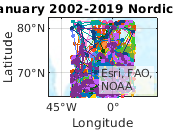

for xx = 1:18
    i = max(ERA5NordicW(xx).Data.track_id);
    J = ERA5NordicW(xx).Data(ERA5NordicW(xx).Data.month == 1,:);
    for b = 0:i
        latJ = J.lat(J.track_id == b);
        lonJ = J.lon(J.track_id == b);
        geoplot(latJ,lonJ,'.-','Color',mycolours2(xx,:));
        hold on
    end
end
geobasemap('topographic')
title ('January 2002-2019 Nordic ERA5')
exportgraphics(gca,'JanTracksERA5Nordic.png',"Resolution",300);